## Four Bar Mechanism - Position, Velocity and Acceleration Analysis

Mubasshir Akhtar

21ME01058

#### System

The system is a four bar mechanism that follows the looks as follows

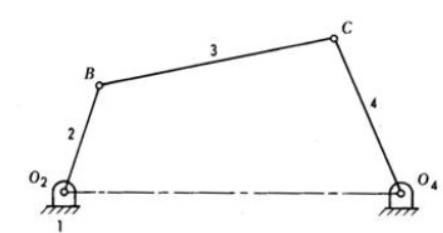

All links follow Grashof criterion and the limk 2 undergoes complete rotation. All angles are measured in the anticlockwise direction and the angles assocated with links are $\theta_1 ,\theta_2 ,\theta_3$ and $\theta_4$ respectively.

#### Inputs

Values of link lengths and theta_2 are initialised following the Grashof criterion

Link lengths are taken in millimetres and angles are taken in degrees.

L1 = 90;
L2 = 40;
L3 = 76;
L4 = 66;
theta_2 = 60;


#### Newton-Raphson's Method

The equations that need to be solved in the position analysis of 4 bar mechanism are non-linear and cannot be solved directly and need to be approximated by the Newton-Raphson's method

          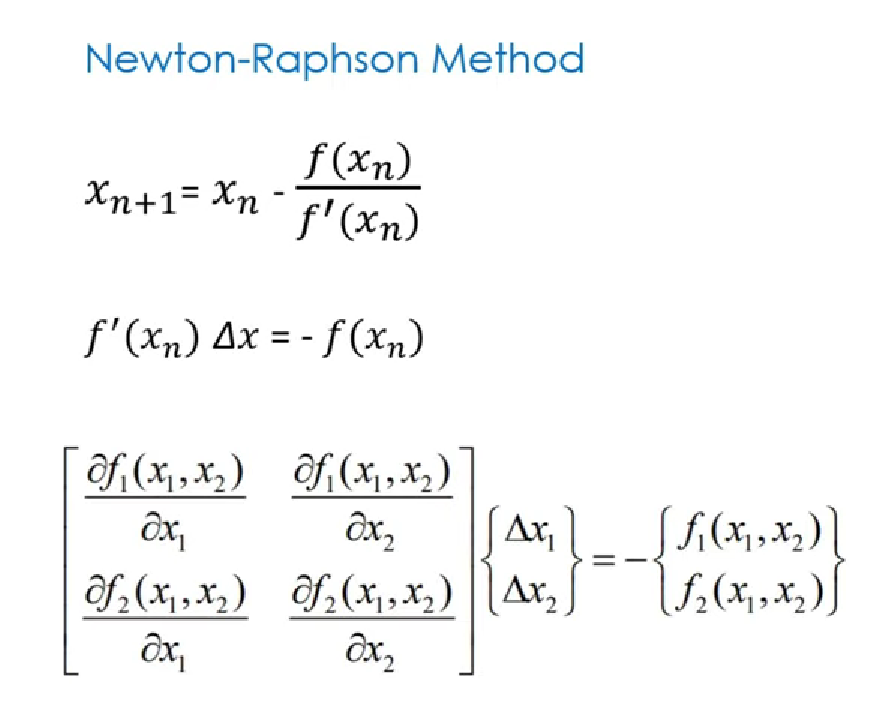

where $f_1 =-L_1 +L_2 \cos \left(\theta_2 \right)+L_3 \cos \left(\theta_3 \right)+L_4 \cos \left(180+\theta_4 \right)$ and   $f_2 =L_2 \sin \left(\theta_2 \right)+L_3 \sin \left(\theta_3 \right)+L_4 \sin \left(180+\theta_4 \right)$

Substituting  these functions in the Newton-Raphson equations and simplifying gives

        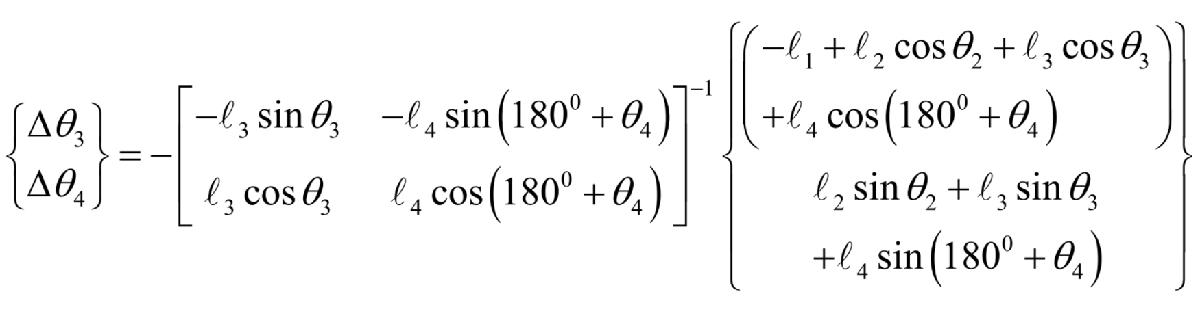

To use this method, an initial guess of the values of theta3 and theta4 is taken and values are iterated over many times to get closer to the answer

#### Initial Solution

angle_3 = 10;
angle_4 = 50;
iter = 0;
sol = [angle_3;angle_4];  %Defining a solution matrix containing the values of theta 3 and 4

#### While Loop

while iter < 500                     %Iterating through the formula to approximate the values of theta 3 and theta 4
    
    f = [(-L1 + L2*cosd(theta_2) + L3*cosd(sol(1)) + L4*cosd(180+sol(2)));
         (L2*sind(theta_2) + L3*sind(sol(1)) + L4*sind(180+sol(2)))];
    
    df = [(-L3*sind(sol(1))), (-L4*sind(180+sol(2))) ;
          (L3*cosd(sol(1))), (L4*cosd(180+sol(2)))];
    
    sol = sol - (df\f);
    
    iter = iter + 1;

end

theta_3 = sol(1)

theta_3 = 24.3655

theta_4 = sol(2)

theta_4 = 90.6628

### Velocity Analysis

The velocities of the end points of the links are given by the following formulae

  
$$\begin{array}{l}
v_A \;=\omega_2 \;\hat{k} \times r_{O_2 A} \\
v_{B\;\textrm{wrt}\;\textrm{O2}\;} =v_A +\omega_3 \times r_{\textrm{AB}} \\
v_{B\;\textrm{wrt}\;O\;4\;} =\omega_4 \hat{k} \times r_{O_4 B} 
\end{array}$$
       

Since C is a single point, $v_{C\;\textrm{due}\;\textrm{to}\;\textrm{link}\;2} =v_{C\;\textrm{due}\;\textrm{to}\;\textrm{link}\;4} \;$. So we can solve this equation to get $\omega_3$ and $\omega_4$ to get velocity of C

w2 = 12;          % In rad/s

% Position vectors using trignometric relations. These are divided by 1000 to express length in metres
rO2B = [L2*cosd(theta_2) L2*sind(theta_2) 0]./1000;
rBC = [L3*cosd(theta_3) L3*sind(theta_3) 0]./1000;
rO4C = [L4*cosd(theta_4) L4*sind(theta_4) 0]./1000;

k = [0 0 1];    %The unit vector along z direction

V_B = w2*cross(k,rO2B);
Vel_mag_B = norm(V_B,2)      % Magnitude of velocity at point B in m/s

Vel_mag_B = 0.4800


syms w3 w4

V_C1 = V_B + w3*cross(k,rBC);
V_C2 = w4*cross(k,rO4C);

eqn_vel = V_C1 - V_C2 == 0;
S = solve(eqn_vel,[w3 w4]);

w3 = double(S.w3)         %Storing the value in decimal format

w3 = -3.5177

w4 = double(S.w4)         %Storing the value in decimal format

w4 = 4.6275


V_C = double(subs(V_C2,w4));
Vel_mag_C = norm(V_C,2)             % Magnitude of velocity at point C in m/s

Vel_mag_C = 0.3054

### Acceleration Analysis

There are two components of acceleration of any point on the link; tangential acceleration and radial acceleration.

The tangential acceleration is given by $a_t =\vec{\alpha} \times \vec{r}$ and the radial acceleration is given by $a_r =-\left(\vec{\omega} \times \vec{\omega} \right)\times \vec{r}$

The total acceleration is then given by $a=a_t +a_r =\vec{\alpha} \times \vec{r} -\left(\vec{\omega} \times \vec{\omega} \right)\times \vec{r}$

The accelerations of various points are given by 


$$\begin{array}{l}
a_A =\vec{\alpha_2 } \times \vec{r_{\textrm{O2A}} } -\left(\vec{\omega} \times \vec{\omega} \right)\times \vec{r_{\textrm{O2A}} } \\
a_{B\;\textrm{wrt}\;\textrm{O2}} =a_A +\vec{\alpha_3 } \times \vec{r_{\textrm{O2A}} } -\left(\vec{\omega} \times \vec{\omega} \right)\times \vec{r_{\textrm{O2A}} } \\
a_{B\;\textrm{wrt}\;O4} =\vec{\alpha_4 } \times \vec{r_{\textrm{O4B}} } -\left(\vec{\omega} \times \vec{\omega} \right)\times \vec{r_{\textrm{O4B}} } 
\end{array}$$


Since C is a single point and has a single value of total acceleration, $a_{C\;\textrm{due}\;\textrm{to}\;\textrm{link}\;3} =a_{C\;\textrm{due}\;\textrm{to}\;\textrm{link}\;4}$. So we can solve this equation to get $\alpha_3$ and $\alpha_4$ to get acceleration of C

alpha_2 = -30;             % In rad/s2
a_B = (alpha_2*cross(k,rO2B)) - ((w2)^2)*rO2B;
acc_mag_B = double(norm(a_B,2))             % Magnitude of acceleration at point B in m/s^2

acc_mag_B = 5.8837


syms alpha_3 alpha_4

a_C1 = a_B + alpha_3*cross(k,rBC) - ((w3)^2)*rBC;
a_C2 = alpha_4*cross(k,rO4C) - ((w4)^2)*rO4C;

eqn_acc = a_C1 - a_C2 == 0;
R = solve(eqn_acc,[alpha_3 alpha_4]);

alpha3 = double(R.alpha_3)                  %Storing the value in decimal format

alpha3 = 65.1159

alpha4 = double(R.alpha_4)                  %Storing the value in decimal format

alpha4 = 72.0571


a_C = double(subs(a_C2,alpha4));
acc_mag_C = double(norm(a_C,2))              % Magnitude of acceleration at point C in m/s^2

acc_mag_C = 4.9613

References:

[https://github.com/xdynemo/mechanisms](https://github.com/xdynemo/mechanisms)

Images adopted from 

[1] engineering.myindialist.com

[2] savemyexams.co.uk